# **Amar Ramdas - 4461487 - OVM 3**

## **Exercise 1:**

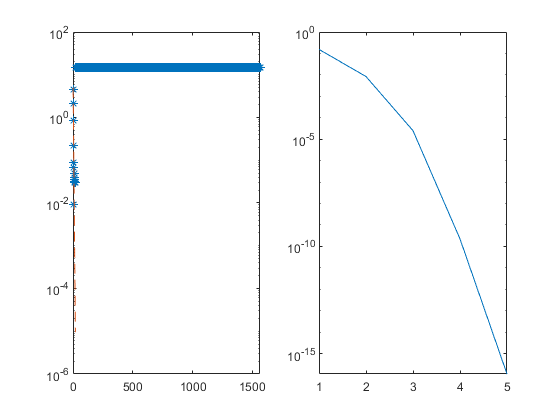

exact = fzero(inline('0.5*(1+erf(x/sqrt(2))) + exp(x)- 2'), 1);
x0 = 1;
x = x0;
xdiff = 1;
k = 1;
kmax = 100;
tol = 1e-8;

for i=1:20
    dotline(i) = 10*1/2^i;
end

while (xdiff >= tol && k< kmax)
    Fval = 0.5*(1+erf(x/sqrt(2))) + exp(x) - 2;
    Fprime = exp(-0.5*x^2)/sqrt(2*pi) + exp(x);
    increment = Fval/Fprime;
    x=x- increment;
    xnewton(k) = x;
    newterr(k) = abs(xnewton(k)-exact);
    k = k+1;
    xdiff = abs(increment);
end

eps_abs = 1e-5;
eps_step = 1e-5;
a = 0.0;
b = 10.0;
g=1;
while (b - a >= eps_step || ( abs( f(a) ) >= eps_abs && abs( f(b) )  >= eps_abs ) )
    c = (a + b)/2;
    if ( f(c) == 0 )
        break;
    elseif ( f(a)*f(c) < 0 )
        b = c;
    else
        a = c;
    end
    arra(g)=a;
    arrb(g)=b;
    arrc(g)=c;
    g = g+1;
    binomerror(g) = abs(c - 0.4);
end



figure;
subplot(1,2,1)
semilogy(binomerror, '*')
hold on;
semilogy(dotline, '--')
hold off;
%make here your first plot
subplot(1,2,2)
semilogy(newterr)

## **Exercise 2:**

**a) **Solve exercise P14.1 from Higham's book (page 138). 

%CH14 Program for Chapter 14
% Computes implied volatility for a European call
%%%%%%%%%%% parameters %%%%%%%%%%
r=0.03; S = 2; E = 2; T = 3; tau = T; sigma_true = 0.3;
[C_true, Cdelta, P_true, Pdelta] = ch08(S,E,r,sigma_true,tau);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%starting value
sigmahat = sqrt(2*abs( (log(S/E) + r*T)/T ) );

%%%%%% Newton’s method %%%%%
tol = 1e-8;
sigma = sigmahat;
sigmadiff = 1;
k = 1;
kmax = 100;
while (sigmadiff >= tol && k< kmax)
    [C, Cdelta, Cvega, P, Pdelta, Pvega] = ch10(S,E,r,sigma,tau);
    increment = (P-P_true)/Pvega;
    sigma = sigma - increment;
    k = k+1;
    sigmadiff = abs(increment);
end
sigma

sigma = 0.3000

Check whether the Newton-Raphson method also performs well for deep in-the-

money options.  Give arguments for your observations

%Repeating with very large E
%%%%%%%%%%% parameters %%%%%%%%%%
r=0.03; S = 2; E = 200000; T = 3; tau = T; sigma_true = 0.3;
[C_true, Cdelta, P_true, Pdelta] = ch08(S,E,r,sigma_true,tau);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%starting value
sigmahat = sqrt(2*abs( (log(S/E) + r*T)/T ) );

%%%%%% Newton’s method %%%%%
tol = 1e-8;
sigma = sigmahat;
sigmadiff = 1;
k = 1;
kmax = 100;
while (sigmadiff >= tol && k< kmax)
    [C, Cdelta, Cvega, P, Pdelta, Pvega] = ch10(S,E,r,sigma,tau);
    increment = (P-P_true)/Pvega;
    sigma = sigma - increment;
    k = k+1;
    sigmadiff = abs(increment);
end
sigma

sigma = 0.8946

**The sigma changes meaning the volatility/variance increases and it's not the same as sigma_true anymore.**

b) Acquire some real option data, either electronically or via a news paper, of  a  company  whose  name  starts  with  your  initial  or  the first  letter  of  your  surname and create a  figure like Figure 14.2. Plot and discuss the implied volatility as the strike price varies. 

**Got AEX data from euronext.**

r=0.05;
% sigmahat = sqrt(2*abs((log(S)/E + r(T-t))/(T-t)));

strikeprices = [516.000, 517.000, 518.000, 519.000];
bidprice = [4.150, 3.450, 2.900, 2.4000]

bidprice =     4.1500    3.4500    2.9000    2.4000


timemonths = [0.75, 0.75, 0.75, 0.75];
timeyrs = timemonths./12;

Volatility = blsimpv(518, strikeprices, r, timeyrs, bidprice, 'Limit', 0.5)

Volatility =     0.0349    0.0361    0.0385    0.0402


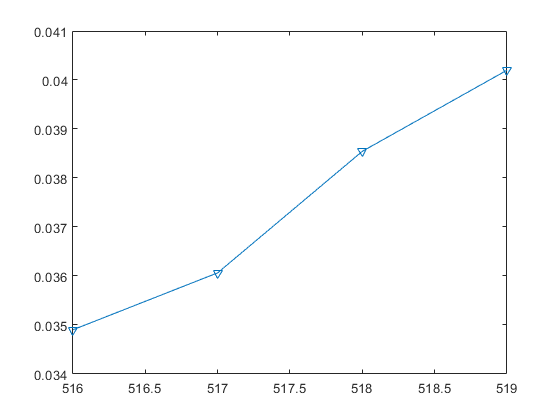


figure;
plot(strikeprices, Volatility, 'v-')

## Exercise 3:

Solve Exercise 14.2 from Higham's book page 13

function y = f(x)
y = N(x) - 2/3;
end

function l = N(w)
l = 1/sqrt(2*pi)*integral(@(x) exp(-(x.^2)/2),-inf, w);
end

function [C, Cdelta, P, Pdelta] = ch08(S,E,r,sigma,tau)
% Program for Chapter 8
% This is a MATLAB function
%
% Input arguments: S = asset price at time t
% E = Exercise price
% r = interest rate
% sigma = volatility
% tau = time to expiry (T-t)
%
% Output arguments: C = call value, Cdelta = delta value of call
% P = Put value, Pdelta = delta value of put
%
% function [C, Cdelta, P, Pdelta] = ch08(S,E,r,sigma,tau)
if tau > 0
    d1 = (log(S/E) + (r + 0.5*sigma^2)*(tau))/(sigma*sqrt(tau));
    d2 = d1 - sigma*sqrt(tau);
    N1 = 0.5*(1+erf(d1/sqrt(2)));
    N2 = 0.5*(1+erf(d2/sqrt(2)));
    C = S*N1-E*exp(-r*(tau))*N2;
    Cdelta = N1;
    P=C+ E*exp(-r*tau) - S;
    Pdelta = Cdelta - 1;
else
    C = max(S-E,0);
    Cdelta = 0.5*(sign(S-E) + 1);
    P = max(E-S,0);
    Pdelta = Cdelta - 1;
end
end

function [C, Cdelta, Cvega, P, Pdelta, Pvega] = ch10(S,E,r,sigma,tau)
% Program for Chapter 10
% This is a MATLAB function
%
% Input arguments: S = asset price at time t
% E = exercise price
% r = interest rate
% sigma = volatility
% tau = time to expiry (T-t)
%
% Output arguments: C = call value, Cdelta = delta value of call
% Cvega = vega value of call
% P = Put value, Pdelta = delta value of put
% Pvega = vega value of put
%
% function [C, Cdelta, Cvega, P, Pdelta, Pvega] = ch10(S,E,r,sigma,tau)
if tau > 0
    d1 = (log(S/E) + (r + 0.5*sigma^2)*(tau))/(sigma*sqrt(tau));
    d2 = d1 - sigma*sqrt(tau);
    N1 = 0.5*(1+erf(d1/sqrt(2)));
    N2 = 0.5*(1+erf(d2/sqrt(2)));
    C = S*N1-E*exp(-r*(tau))*N2;
    Cdelta = N1;
    Cvega = S*sqrt(tau)*exp(-0.5*d1^2)/sqrt(2*pi);
    P=C+ E*exp(-r*tau) - S;
    Pdelta = Cdelta - 1;
    Pvega = Cvega;
else
    C = max(S-E,0);
    Cdelta = 0.5*(sign(S-E) + 1);
    Cvega = 0;
    P = max(E-S,0);
    Pdelta = Cdelta - 1;
    Pvega = 0;
end
end

